# 3.2 Auto-regressive Random Process

Alexandre Rey, MSE, MA-StatDig, 03.2022

clear;
rng('default');

addpath('../functions/');

## Estimation of autocorrelation of random process (ComEx 3.2)

In many applications it is necessary to be able to efficiently estimate the autocorrelation sequence of a random process from a finite number of samples e.g. $x(n)$ for $n=0\dots N-1$.

The autocorrelation may be estimated using the sample autocorrelation:

$\hat{r}_x(k)=\frac{1}{N}\sum_{n=0}^{N-1}x(n)x^*(n-k)$                     (1)

For this estimation we assume the samples outside the interval $0\dots N-1$are equal to 0. Since, this is assumed we could write the sample autocorrelation as a convolution:

$\hat{r}_x(k)=\frac{1}{N}[x(k)*x^*(-k)]$                            (2)

The discrete-time Fourier transform of $\hat{r}_x(k)$ is the magnitude squared of the discrete-time Fourier transform of $x(n)$ scaled by $1/N$:

$\sum_{k=-N+1}^{N-1}\hat{r}_x(k)e^{-jk\omega}=\frac{1}{N}|X(e^{-jk\omega})|^2$             (3)

where $X(e^{-jk\omega}) = \sum_{n=0}^{N-1}x(n)e^{-jn\omega}$

## First experiment: test with a simple signal x(n)

- With a signal $x(n) = 1$ (deterministic) for $n=1\dots N-1$ with $N=8$. Compute the sample autocorrelation using (1) write a function `[rxhat,k]= SampleAutocorr(xn)`

- Compute the sample autocorrelation by the convolution $\frac{1}{N} (x(k)*X(-k))$ and show that give the same result.

- Verify the property given by (3), for that compute the DFT of the sample autocorrelation `rxhat `and compare to the squared of the module DFT of $x(n)$

- Find the sample autocorrealtion using the FFT of $x(n)$ with $N=8$, $16$ or $32$ samples. Compare the results.

- Try all the precedent steps with a gaussian white process: `x(n)=randn(1,N)`

N = 1000;
n = 0:N-1;

%xn = ones(1,N);     % step unit
xn = randn(1,N);   % random process

% with self made function autocorrelation function
[rxhat, k] = mySampleAutocorr(xn, 'biased');  % normalized by N with 'biased'

Compute with the function `conv()` and the function `fliplr()` the autocorrelation of $xn$:

rxhatconv = conv(xn, fliplr(xn)) ./ N;

Compare the two calculation methods

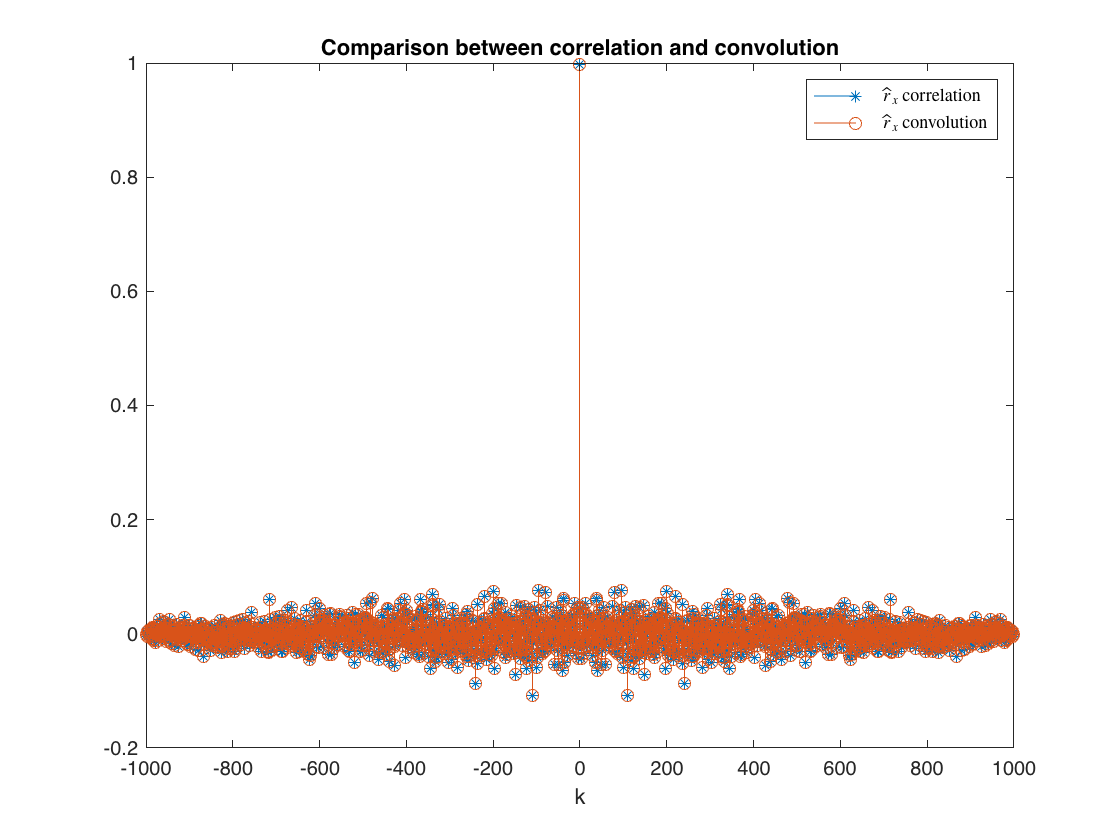

figure;
    stem(k, rxhat, '*');
    hold on;
    stem(k, rxhatconv);
    hold off;
    title('Comparison between correlation and convolution');
    legend('$\hat{r}_x$ correlation', '$\hat{r}_x$ convolution', ...
           'Interpreter', 'latex');
    xlabel('k')

Compute the DFT of the signal $x(n)$ ($N$ samples) with NFFT sample of the DFT (try 8, 16, 32), compute the DFT and compute the square of the magnitude:

NFFT = 2048; % N*2

w = -pi : 2*pi/NFFT : pi-2*pi/NFFT;
f = w/2/pi;
%Ejw = exp(-1j*n'*w);
%Xsq_fft = abs(xn*Ejw).^2 ./ N
Xsq_fft = abs(fftshift(fft(xn, NFFT))).^2 ./ N;

Compute the DFT of the sample autocorrelation sequence $P_x$ and verify that is real:

For FFT use it is important to have $\hat{r}_x$ as a entire periode of a periodic sequence of length $2N$, $\hat{r}_x$ must be symetric and has $2N-1$ samples so to ensure simmetricity and have a right computation of the DFT we need to add a 0 sample at the beginning of `rxhat` previsouly computed:

$\hat{r}_x(k) = [\mathbf{0}, \hat{r}_x\left(-\frac{N}{2}+1\right),\dots, \hat{r}_x(0), \dots, \hat{r}_x\left(\frac{N}{2}\right)]$ this vector now has $2N$ samples and has the same energy than $\hat{r}_x(k)$ 

rxhat_p = [zeros(1,NFFT/2 - N+1), rxhat, zeros(1, NFFT/2 - N)];
Pxfft = fftshift(fft(fftshift(rxhat_p), NFFT));

Must be real values and positives ! So take real part after verification.

Pxfftr = real(Pxfft);

Plot the power spectrum $P_x$ computed with $x(n)$ directly or with the sample autocorrelation sequence:

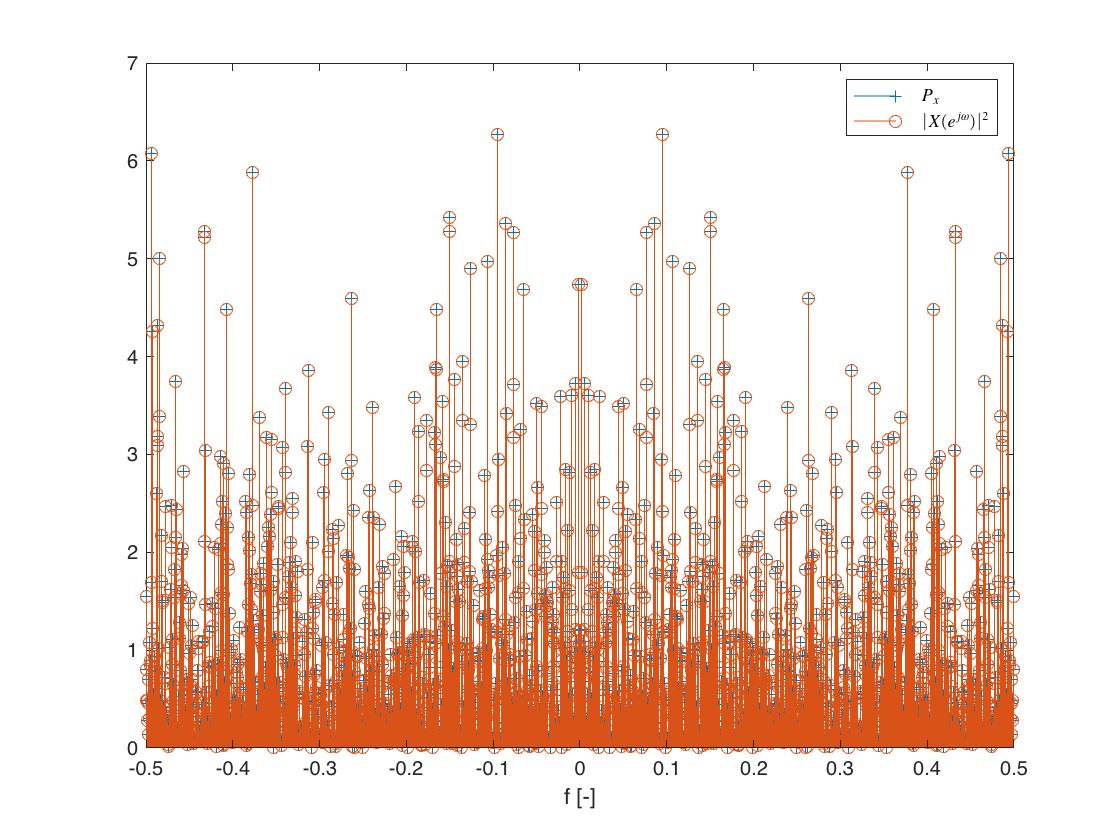

figure;
    stem(f, Pxfftr, '+');
    hold on;
    stem(f, Xsq_fft, 'o');
    hold off;
    xlabel('f [-]');
    legend('$P_x$', '$|X(e^{j\omega})|^2$', ...
           'Interpreter', 'latex');

## Compute the sample autocorrelation by the inverse DFT of the power spectrum:

We could compute the sample autocorrelation estimation by the inverse of the squared of the DFT of $x(n)$.

To obtain the same autocorrelation vector you need to remove the useless zeros at the beginning and the end of the vector they was added when the power spectrum was computed.

rxhatfft = fftshift(ifft(fftshift(Pxfft)));

Plot the sample autocorrelation directly computed from $x(n)$ and from the power spectrum $P_x$ computed with the square of the DFT magnitude of $x(n)$. Try with NFFT=8,16 or 32.

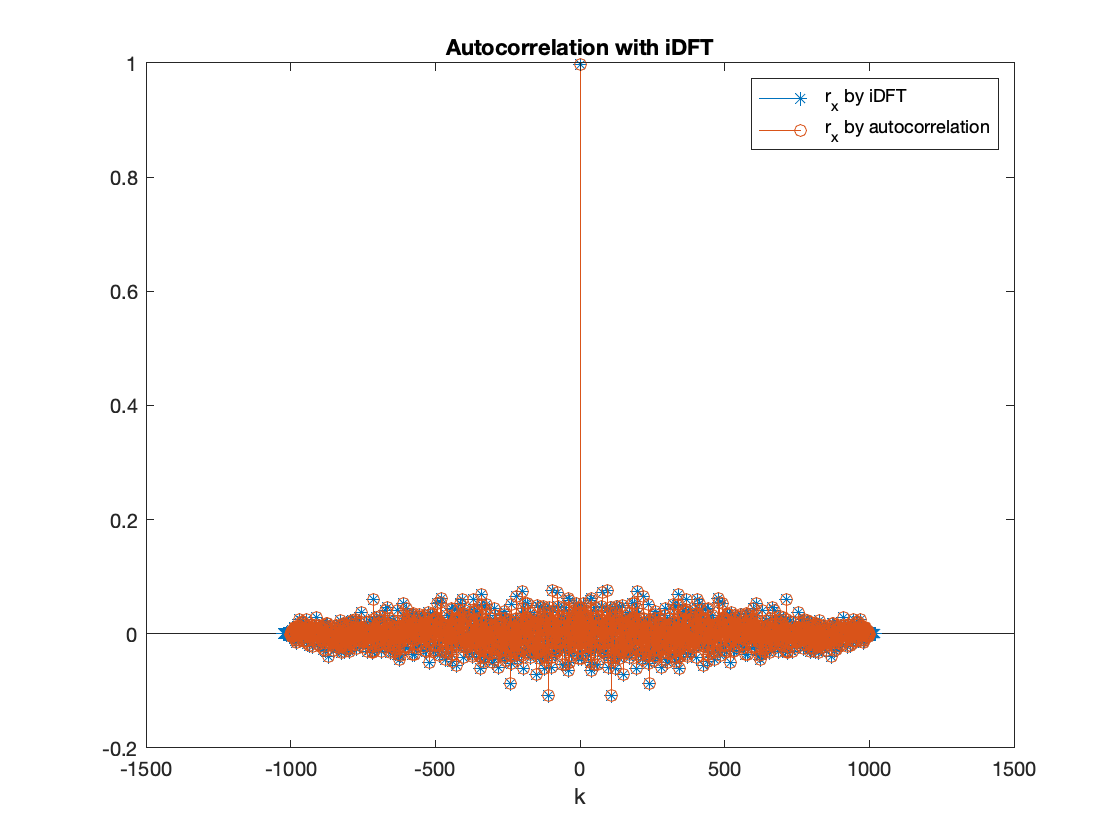

k_dft = -(NFFT/2):1:(NFFT/2)-1;
figure;
    stem(k_dft, rxhatfft, '*');
    hold on;
    stem(k, rxhat, 'o');
    hold off;
    title('Autocorrelation with iDFT');
    legend('r_x by iDFT','r_x by autocorrelation');
    xlabel('k');